clc; clear;
% load('xdata.mat')
% load('ydata.mat')

load('hX.mat')
load('hY.mat')

% userfit = fittype({['x']})
userfit = fittype(['a*x+1'])

userfit =      일반 모델:
     userfit(a,x) = a*x+1

ff = fit(X, Y, userfit, 'StartPoint', 1)

ff =      일반 모델:
     ff(x) = a*x+1
     계수(신뢰한계: 95%):
       a =       1.486  (1.444, 1.527)

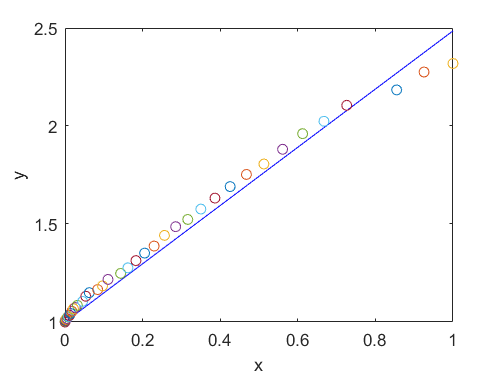

plot(ff, '-b')
legend('off')

for i=1:length(Y)
    hold on
    plot(X(i,1),Y(i,1),'o')
end